
tic
for wt = 1 : 10
  fn = sprintf("resultswt%d", wt);
  Tresultswt{wt} = load(fn);
end

fn = "resultswt1"

Tresultswt = 1×1 cell array
    {1×1 struct}


fn = "resultswt2"

Tresultswt = 1×2 cell array
    {1×1 struct}    {1×1 struct}


fn = "resultswt3"

Tresultswt = 1×3 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt4"

Tresultswt = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt5"

Tresultswt = 1×5 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt6"

Tresultswt = 1×6 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt7"

Tresultswt = 1×7 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt8"

Tresultswt = 1×8 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt9"

Tresultswt = 1×9 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


fn = "resultswt10"

Tresultswt = 1×10 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


toc

Elapsed time is 48.872873 seconds.



tic
for wt = 1 : 10
  solmax{wt} = max(max(Tresultswt{wt}.Tresults));
end

solmax = 1×1 cell array
    {[80.0330]}


solmax = 1×2 cell array
    {[80.0330]}    {[68.1099]}


solmax = 1×3 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}


solmax = 1×4 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}


solmax = 1×5 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}    {[57.9162]}


solmax = 1×6 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}    {[57.9162]}    {[56.5945]}


solmax = 1×7 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}    {[57.9162]}    {[56.5945]}    {[55.5687]}


solmax = 1×8 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}    {[57.9162]}    {[56.5945]}    {[55.5687]}    {[54.7349]}


solmax = 1×9 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}    {[57.9162]}    {[56.5945]}    {[55.5687]}    {[54.7349]}    {[54.0513]}


solmax = 1×10 cell array
    {[80.0330]}    {[68.1099]}    {[62.8800]}    {[59.8612]}    {[57.9162]}    {[56.5945]}    {[55.5687]}    {[54.7349]}    {[54.0513]}    {[53.4358]}


toc

Elapsed time is 10.647597 seconds.



Tresults1_5 = load("resultswt1_5");

Tresults1_5 = struct with fields:
    Tresults: [118637×601 double]


solmax1_5 = max(max(Tresults1_5.Tresults));

solmax1_5 = 72.6739


solmaxwt = [solmax{1},solmax1_5,solmax{2},solmax{3},solmax{4},solmax{5},solmax{6},solmax{7},solmax{8},solmax{9},solmax{10}]

solmaxwt =    80.0330   72.6739   68.1099   62.8800   59.8612   57.9162   56.5945   55.5687   54.7349   54.0513   53.4358


wt = [1, 1.5, 2,3,4,5,6,7,8,9,10]

wt =     1.0000    1.5000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000


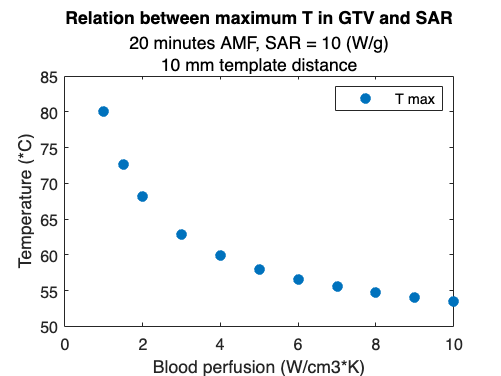


figure
plot(wt,solmaxwt,'.','MarkerSize',20)
title('Relation between maximum T in GTV and SAR')
txt = {'20 minutes AMF, SAR = 10 (W/g)', '10 mm template distance'};
subtitle(txt)
ylabel("Temperature (*C)")
xlabel("Blood perfusion (W/cm3*K)") 
legend("T max")